Exercise 5.3

Mid-point rule: 

    
$$y_{j+1} =y_{j-1} +2hf_j$$
    
$$\Longrightarrow$$
  
$$y_j =y_{j-2} +2hf_{j-1}$$
 

Adam-Bashforth two-step method: 

    
$$y_{j+1} =y_j +\frac{h}{2}\left\lbrack 3f_j -f_{j-1} \right\rbrack$$
  
$$\Longrightarrow$$
  
$$y_j =y_{j-1} +\frac{h}{2}\left\lbrack 3f_{j-1} -f_{j-2} \right\rbrack$$


i) h=0.02

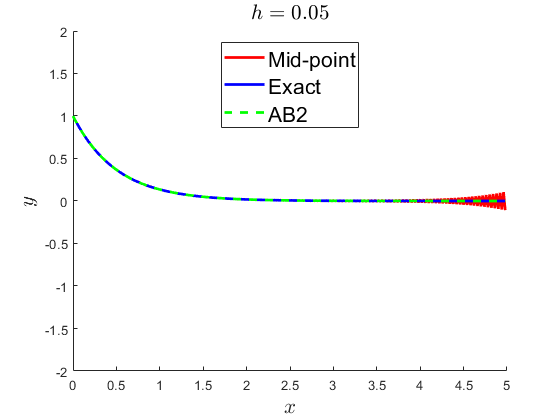

clc
clear
format 
lam=-2;
h=0.02;
tEnd=5;

x(1)=0;
y(1)=1;
f(1)=lam*y(1);

x(2)=x(1)+h;
y(2)=exp(-2*x(2));
f(2)=lam*y(2);

%mid-point
for i=3:tEnd/h
   x(i)=x(i-1)+h;
   y(i)=y(i-2)+2*h*f(i-1);
   f(i)=lam*y(i);
end

%Adams-Bashforth Two-step method, k=2
%See Chapter 2 (page 23) in Lecture notes
yab=y;
fab=f;

for i=3:tEnd/h
   yab(i)=yab(i-1)+0.5*h*(3*fab(i-1)-fab(i-2)) ;
   fab(i)=lam*yab(i);
end
figure(1)
clf
hold on
plot(x,y,'r','LineWidth',2)
plot(x,exp(-2*x),'b','LineWidth',2)
plot(x,yab,'g--','LineWidth',2)
legend('Mid-point','Exact','AB2','Location','north','FontSize',16)
title('$h=0.05$','fontsize',16,'interpreter','latex')
axis([0 5 -2 2])
xlabel('$x$','fontsize',16,'interpreter','latex')
ylabel('$y$','fontsize',16,'interpreter','latex')

ii) h=0.05

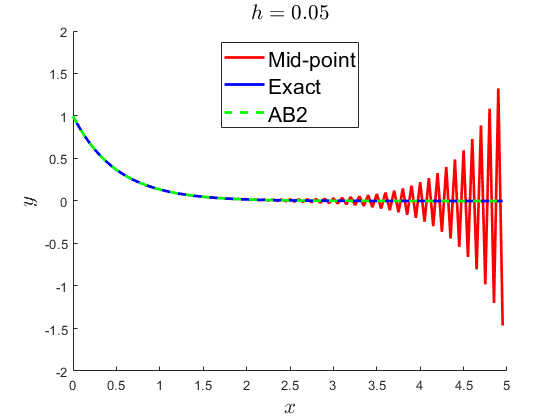

clc
clear
format 
lam=-2;
h=0.05;
tEnd=5;

x(1)=0;
y(1)=1;
f(1)=lam*y(1);

x(2)=x(1)+h;
y(2)=exp(-2*x(2));
f(2)=lam*y(2);

%mid-point rule
for i=3:tEnd/h
   x(i)=x(i-1)+h;
   y(i)=y(i-2)+2*h*f(i-1);
   f(i)=lam*y(i);
end

%Adams-Bashforth Two-step method, k=2
%See Chapter 2 (page 23) in Lecture notes
yab(1:2)=y(1:2);
fab(1:2)=f(1:2);

for i=3:tEnd/h
   yab(i)=yab(i-1)+0.5*h*(3*fab(i-1)-fab(i-2)) ;
   fab(i)=lam*yab(i);
end

figure(2)
clf
hold on
plot(x,y,'r','LineWidth',2)
plot(x,exp(-2*x),'b','LineWidth',2)
plot(x,yab,'g--','LineWidth',2)
legend('Mid-point','Exact','AB2','Location','north','FontSize',16)
title('$h=0.05$','fontsize',16,'interpreter','latex')
axis([0 5 -2 2])
xlabel('$x$','fontsize',16,'interpreter','latex')
ylabel('$y$','fontsize',16,'interpreter','latex')